# PRÁCTICA 12: Deep Learning C-NN para la identificación de dígitos en un sudoku

Se pretende entrenar una red neuronal convolucional para la identificación de los dígitos que aparecen en las celdas de un sudoku captado mediante una cámara, estos dígitos tienen un tipo de fuente determinado que es el que se aprenderá la red. 

Para ello se dispone de un conjunto de imágenes de entrenamiento en las que aparece un único dígito y cuya clasificación es conocida. Estas imágenes están contenidas en el subdirectorio ..\Muestras, el cual posee un conjunto de subcarpetas cuyos nombres se corresponden con la clase a la que pertenecen las imágenes que contienen (del 1 al 0, ya que en lo sudokus no puede aparecer el dígito 0). Las imágenes son de niveles de grises de 28x28. 

Una vez entrenada la red, ésta se va a emplear para identificar los dígitos que aparecen en una nueva imagen que contiene un sudoku. Para ello habrá que segmentar la imagen con el objetivo de localizar las celdas y aislar su contenido, preprocesar cada región segmentada de la imagen y finalmente reconocer el digito mediante la red neuronal. 

## EJERCICIOS

### ENTRENAMIENTO DE LA RED NEURONAL CONVOLUCIONAL (C-NN) 1.

#### E1 Especificar imágenes tanto para el entrenamiento cómo para la validación.

- Generar una estructura de datos con los nombres de los ficheros que contendrán las imágenes empleadas en el entrenamiento, la clase a la que pertenece cada imagen se corresponde con el nombre del subdirectorio que las contiene.

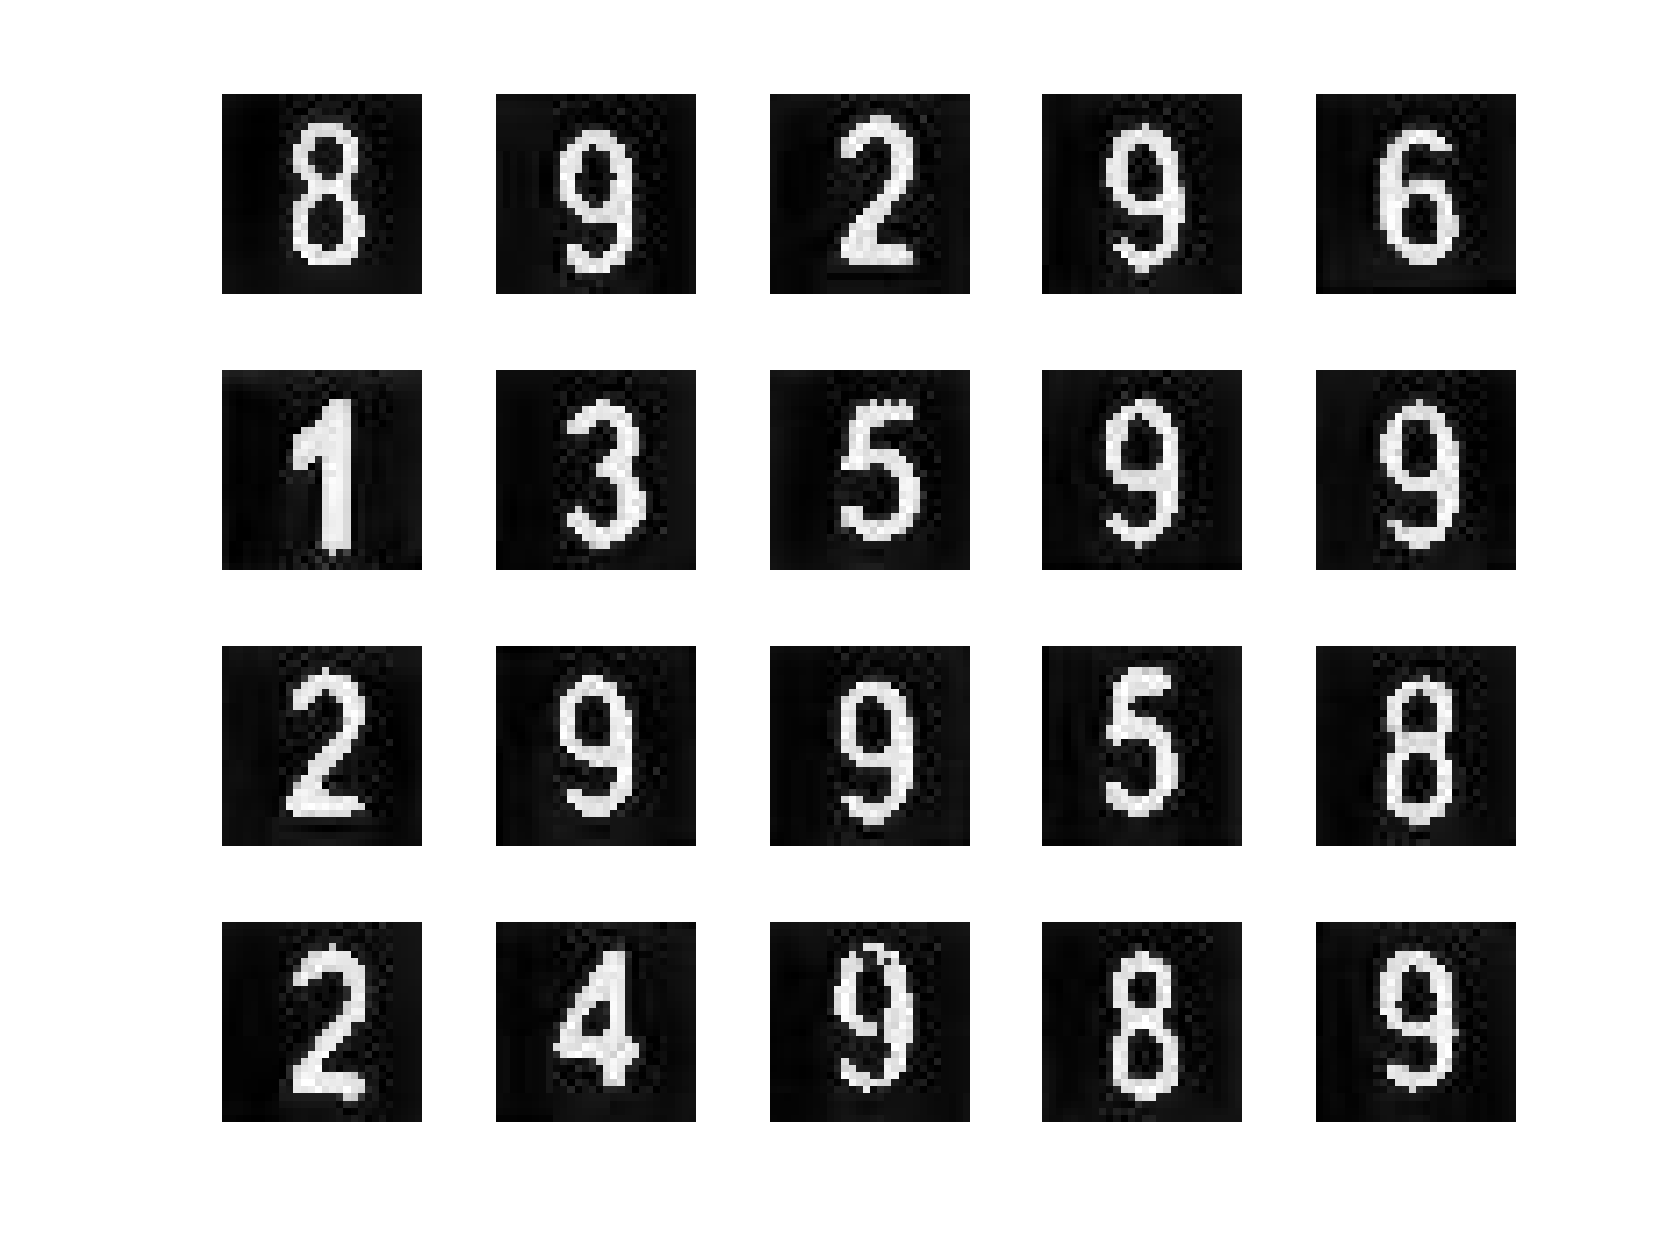

imds = imageDatastore('.\Muestras', ...
 'IncludeSubfolders',true,'LabelSource','foldernames');

% Muestra 20 imágenes de la muestra tomadas al azar
figure('Name','MUESTREO')
perm = randperm(numel(imds.Files),20); % 20 números aleatorios
for k = 1:20
 subplot(4,5,k);
 im = readimage(imds,perm(k));
 % lee una imagen dando su número en la base de datos
 imshow(im);
end

- Separar la muestra en imágenes para el entrenamiento e imágenes de validación (75% y 25% respectivamente en este caso), la variable imdsTrain contiene los nombres de las imágenes para el entrenamiento e imdsValidation los nombres de las imágenes seleccionadas para la validación. 

% Contar el número de muestras por cada clase etiquetada
labelCount = countEachLabel(imds)

labelCount = 9×2 table
    Label    Count
    _____    _____

      1       359 
      2       347 
      3       344 
      4       346 
      5       365 
      6       363 
      7       345 
      8       355 
      9       357 



% Establecer número de imágenes de entrenamiento por cada clase
% 75% para entrenamiento y 25% para validación
numTrainFiles = round(mean(labelCount.Count)*0.75);

% Divide la muestra entre imágenes de entrenamiento y validación
[imdsTrain,imdsValidation]=splitEachLabel(imds,numTrainFiles,'randomize');

#### E2. Definir la estructura de la red convolucional (CNN)

- La red va a contener una capa de entrada de 28x28x1 correspondiente a las dimensiones de las imágenes en niveles de grises, dos capas convolucionales con 8 y 16 filtros respectivamente (3x3 píxeles por filtro), una red full connect con 9 salidas (una por cada tipo de dígito, del 1 al 9) y una capa de salida (indica la clasificación final). 

% Definir la red convolucional CNN
layers = [imageInputLayer([28 28 1]) % Capa de entrada con el tamaño de
% las imágenes de entrada

 convolution2dLayer(3,8,'Padding','same') % Capa de convolución
 batchNormalizationLayer % Capa de normalización
 reluLayer % Capa de rectificación

 maxPooling2dLayer(2,'Stride',2) % Capa de submuestreo

 convolution2dLayer(3,16,'Padding','same')% Capa de convolución
 batchNormalizationLayer % Capa de normalización
 reluLayer % Capa de rectificación

 fullyConnectedLayer(9) % Capa Full Connected
 softmaxLayer % Capa de exponencial normalizada
 classificationLayer]; % Capa de clasificación

#### E3. Definir opciones de entrenamiento (metaparámetros) 

% Opciones de entrenamiento Meta-parámetros
options = trainingOptions('sgdm', ... % Tipo de descenso del gradiente
 'InitialLearnRate',0.01, ... % Tasa de aprendizaje en cada iteración
 'MaxEpochs',4, ... % Número máximo de épocas
 'Shuffle','every-epoch', ... % Cada cuanto se barajan las muestras
 'ValidationData',imdsValidation, ... % Muestra empleada para la validación
 'ValidationFrequency',10, ... % Frecuencia de validación
 'Verbose',false, ... % Mostrar o no notificaciones en comandos
 'Plots','training-progress'); % Presentación gráfica del entrenamiento

#### E4. Entrenamiento de la red 

NOTA: Para poder llevar a cabo el entrenamiento es necesario que el equipo disponga de una tarjeta gráfica dedicada. Si no se dispone de ella se puede emplear uno de los equipos de la Escuela de forma remota. En caso de no poder realizar el entrenamiento se puede cargar la red netSudokus para completar los siguientes ejercicios. 

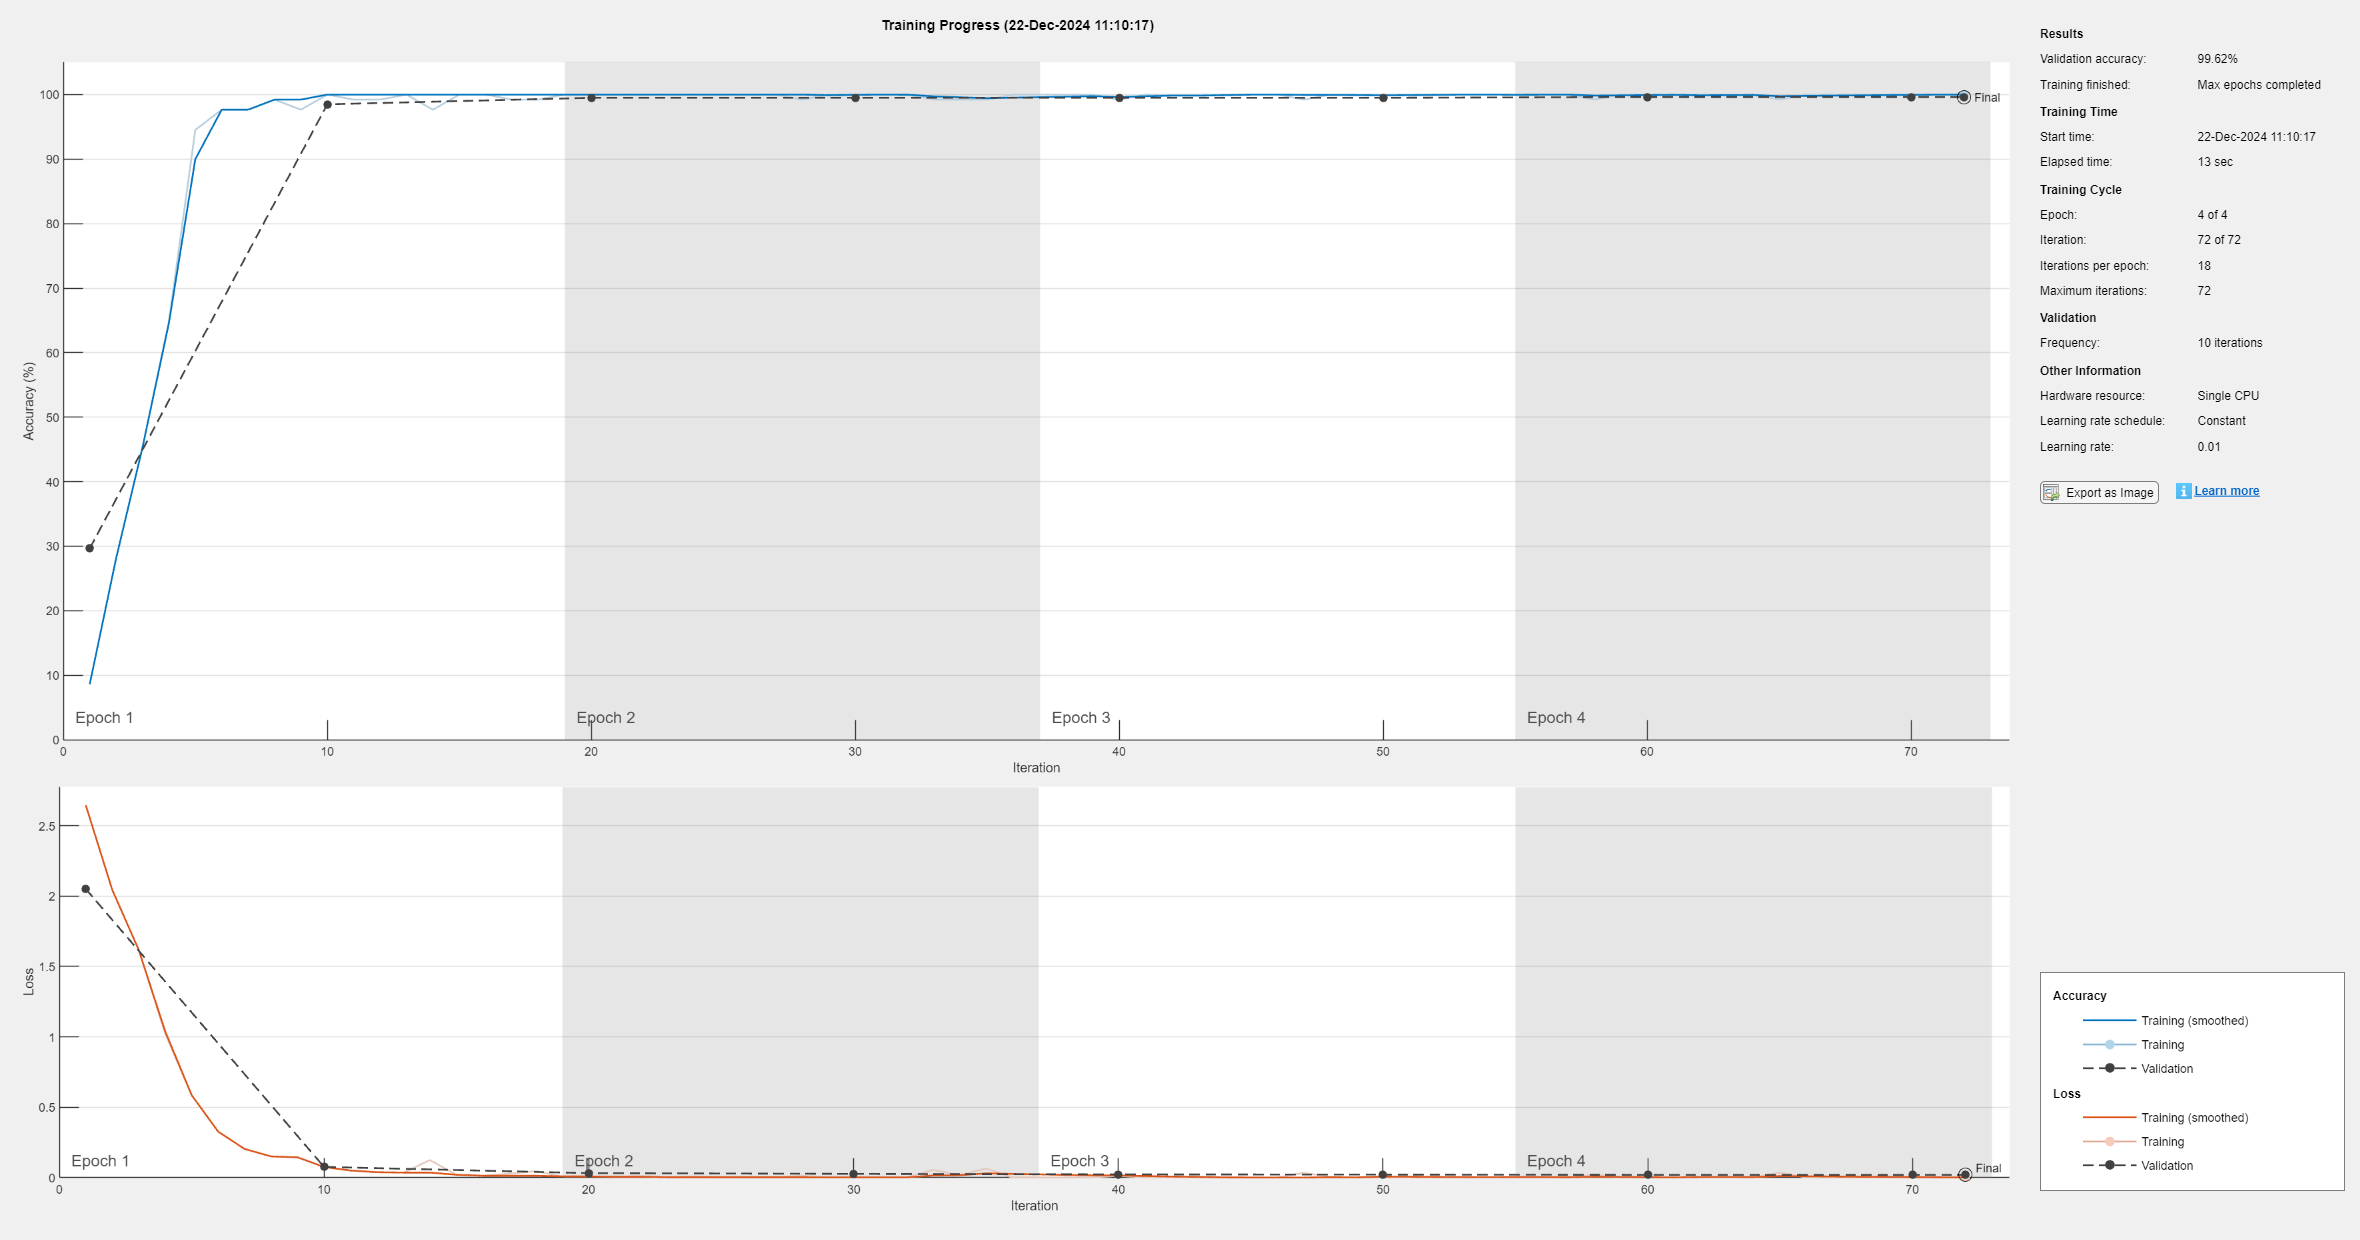

% Entrenar la red
netSudokus = trainNetwork(imdsTrain,layers,options);


%load netsudokus

## EJERCICIOS. CLASIFICACIÓN DE DIGITOS 

Se debe emplear la red entrenada para clasificar los dígitos de un sudoku. Estos sudokus están contenidos en 8 imágenes que van de sudo01.jpg a sudo08.jpg, en el fichero sudokus.mat

load sudokus.mat 

Para realizar este ejercicio se debe emplear el comando de Matlab imcrop(), para segmentar de forma manual un digito, y la función ProprocesaNum() para adaptar dicha imagen a las empleadas en el entrenamiento de la red (28x28x1, con histograma especificado e invertida). El histograma a usar está en el fichero histograma_celda.mat

Ejemplo

 La clasificación del número contenido en la imagen mejorada im_num_p se obtiene empleando la red neuronal entrenada: 

#### E5. Repita este ejemplo con diversas imágenes y dígitos

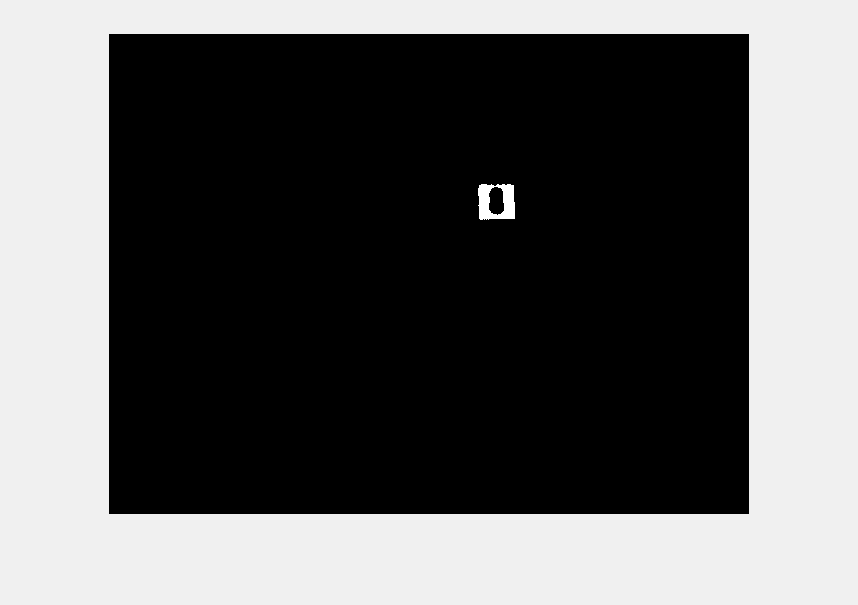

load histograma_celda.mat

ob = cre_isa(rgb2gray(sudo1),10);

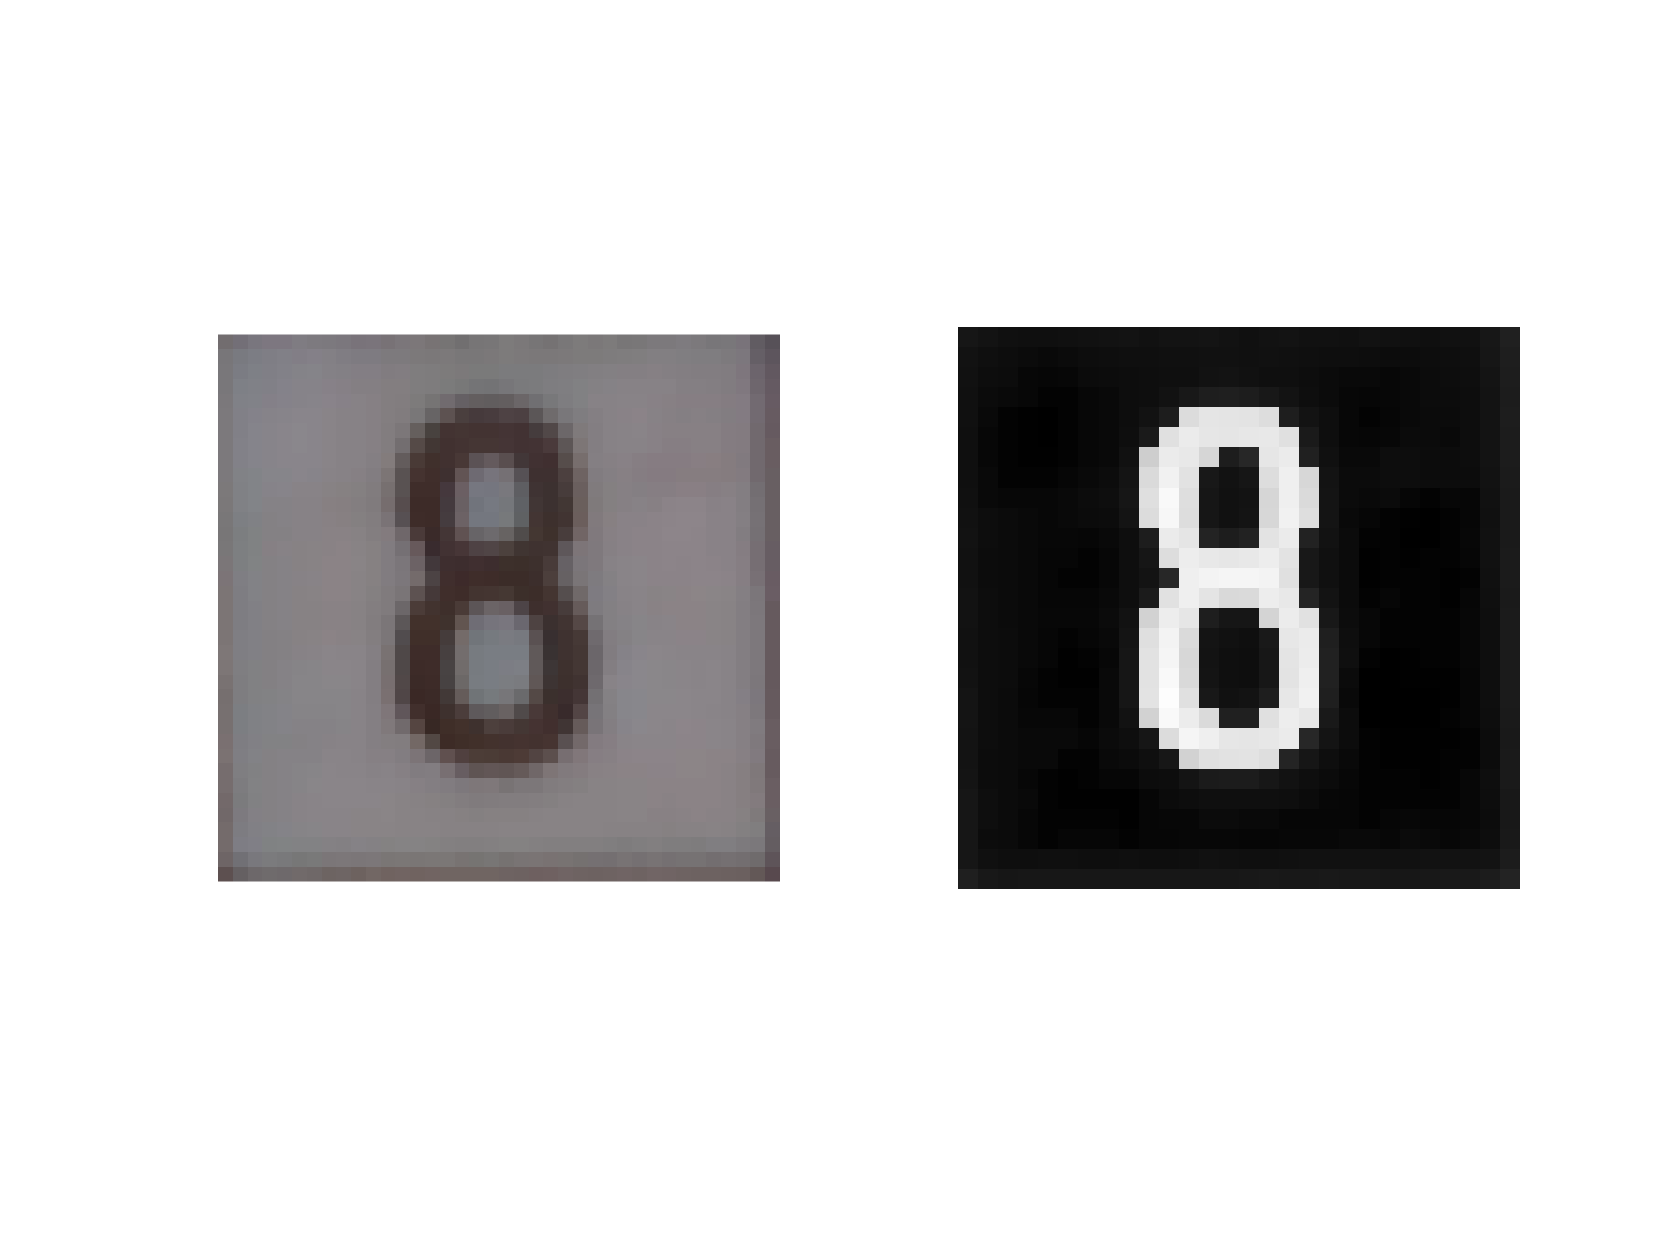

figure
p = regionprops(ob,'BoundingBox');
im_num = imcrop(sudo1,p.BoundingBox); 
im_num_p = PreprocesaNum(im_num,[28,28],h,1); 
subplot(1,2,1), imshow(im_num); 
subplot(1,2,2), imshow(im_num_p);

c = classify(netSudokus,im_num_p)

c = categorical
     8 


### EJERCICIOS . ANÁLISIS IMAGEN SUDOKU

La función BuscarCeldasSudoku, analiza una imagen RGB que contenga un sudoku y devuelve una imagen que sólo contiene el sudoku y una estructura de datos en las que para cada celda suministra la siguiente información : 

- *.im → imagen contenida en la celda, puede ser un dígito o bien estar vacía 

- *.xcen → coordenada x del centro da la celda en la imagen de entrada 

- *.ycen → coordenada y del centro de la celda en la imagen de entrada 

- *.ocu → 0 si la celda está vacía y 1 si la celda está ocupada por un dígito 

Como parámetros de entradas tiene la imagen rgb que contiene un sudoku y un segundo parámetro que indica si se debe o no visualizar el resultado (0/1). 

#### 6. Estudie esta función

Ejemplo

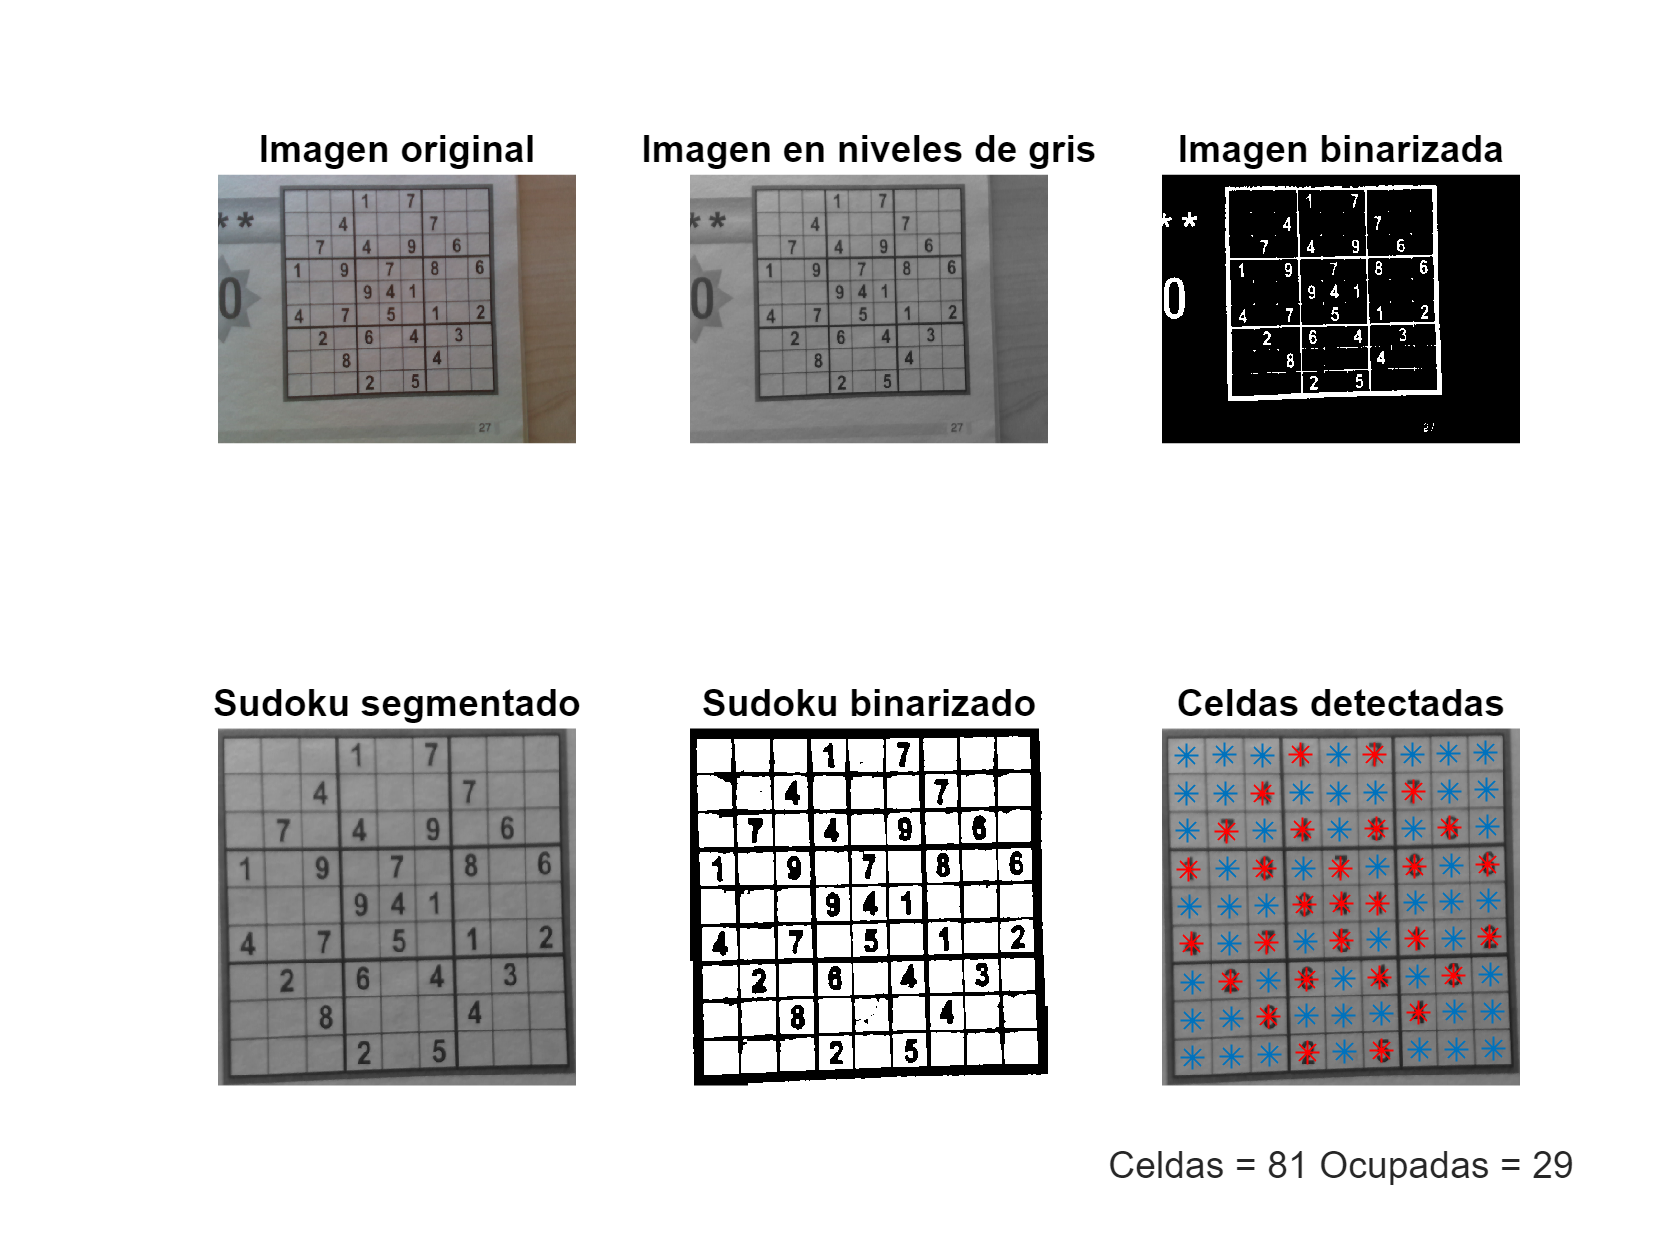

[im_sudo, celdas] = BuscarCeldasSudoku (sudo1,1);

#### E7. Muestre, en una figura con 4 subplots, el contenido de las celdas 12, 14, 16 y 28. 

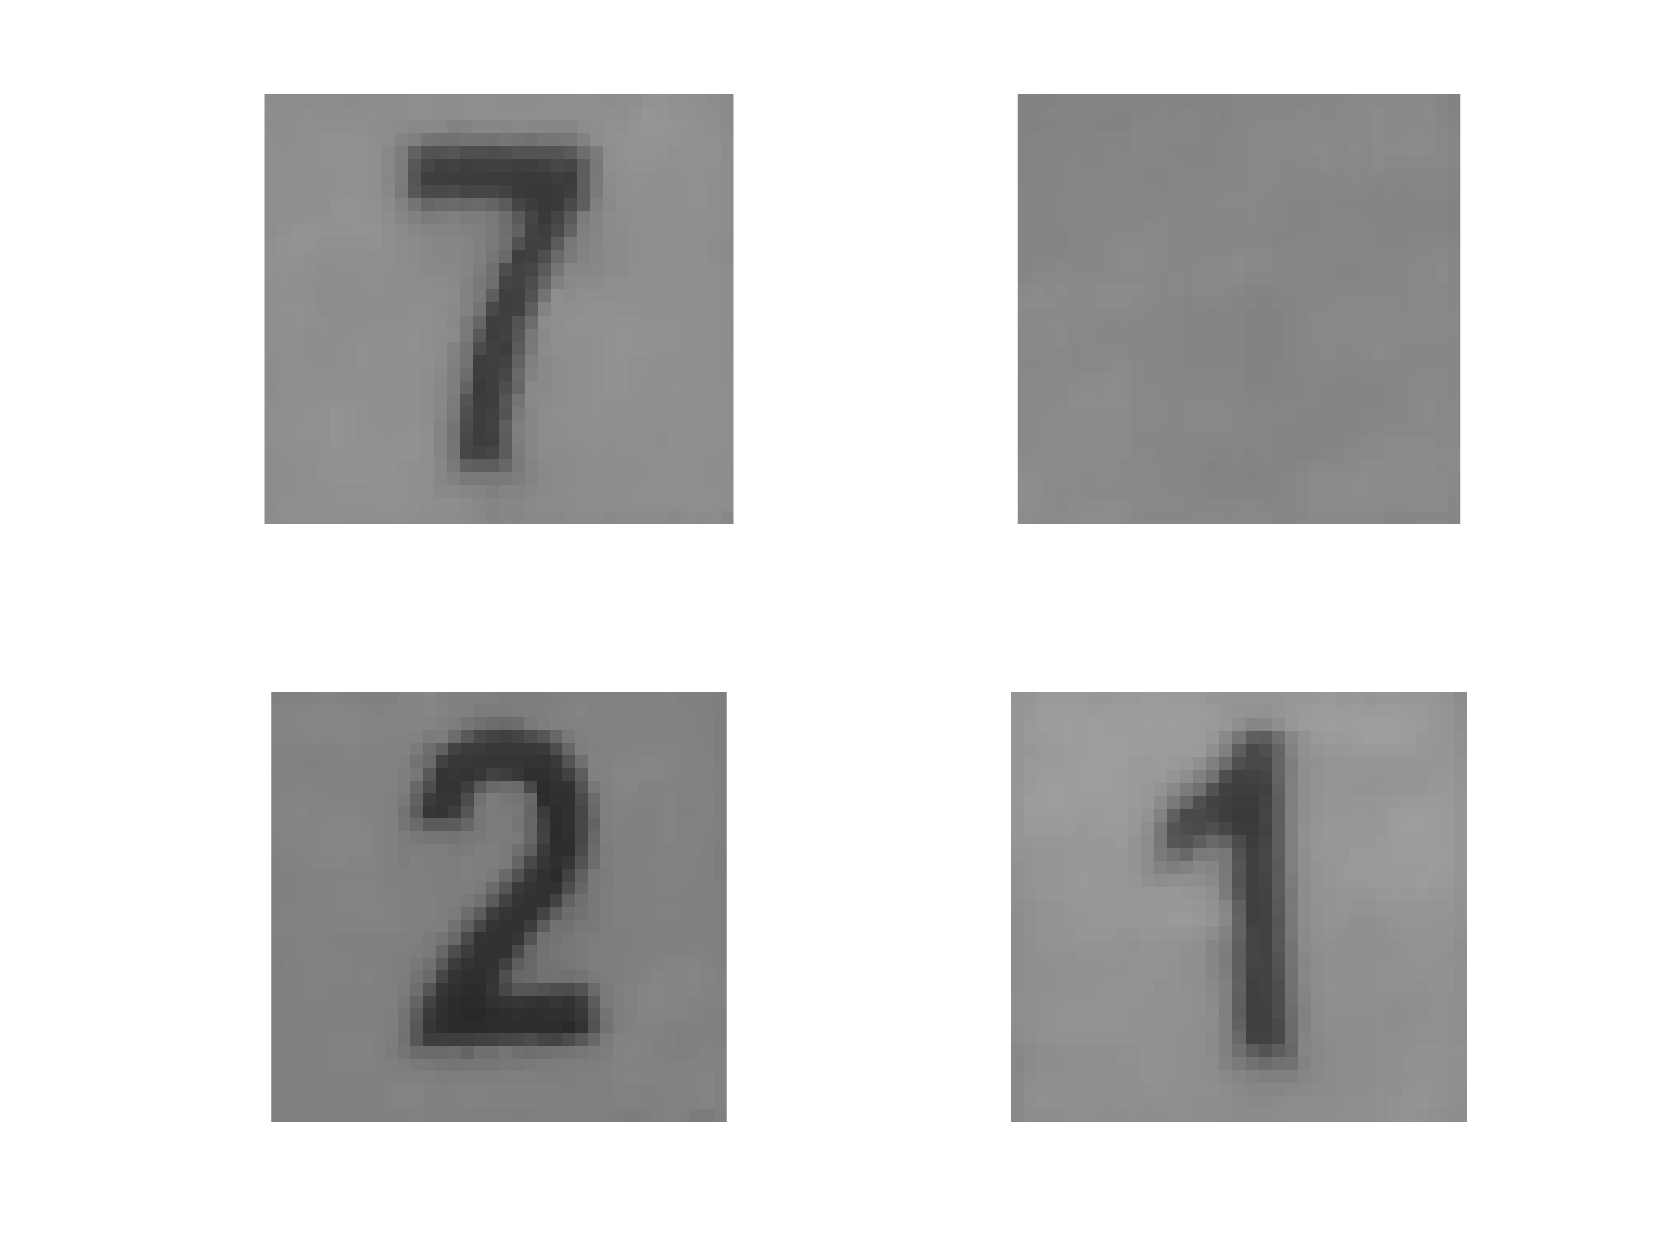

figure
subplot(2,2,1); imshow(celdas(12).im);
subplot(2,2,2); imshow(celdas(14).im);
subplot(2,2,3); imshow(celdas(16).im);
subplot(2,2,4); imshow(celdas(28).im);

#### EJERCICIO 8. 

Realice un programa que admita como entrada una imagen rgb que contiene un sudoku y la red neuronal entrenada en el ejercicio 4, y que como salida proporcione una imagen en la que aparezca superpuesto el digito detectado en cada celda, para ello haga uso de las funciones anteriores. Para la clasificación de cada celda deberá emplear la red neuronal.

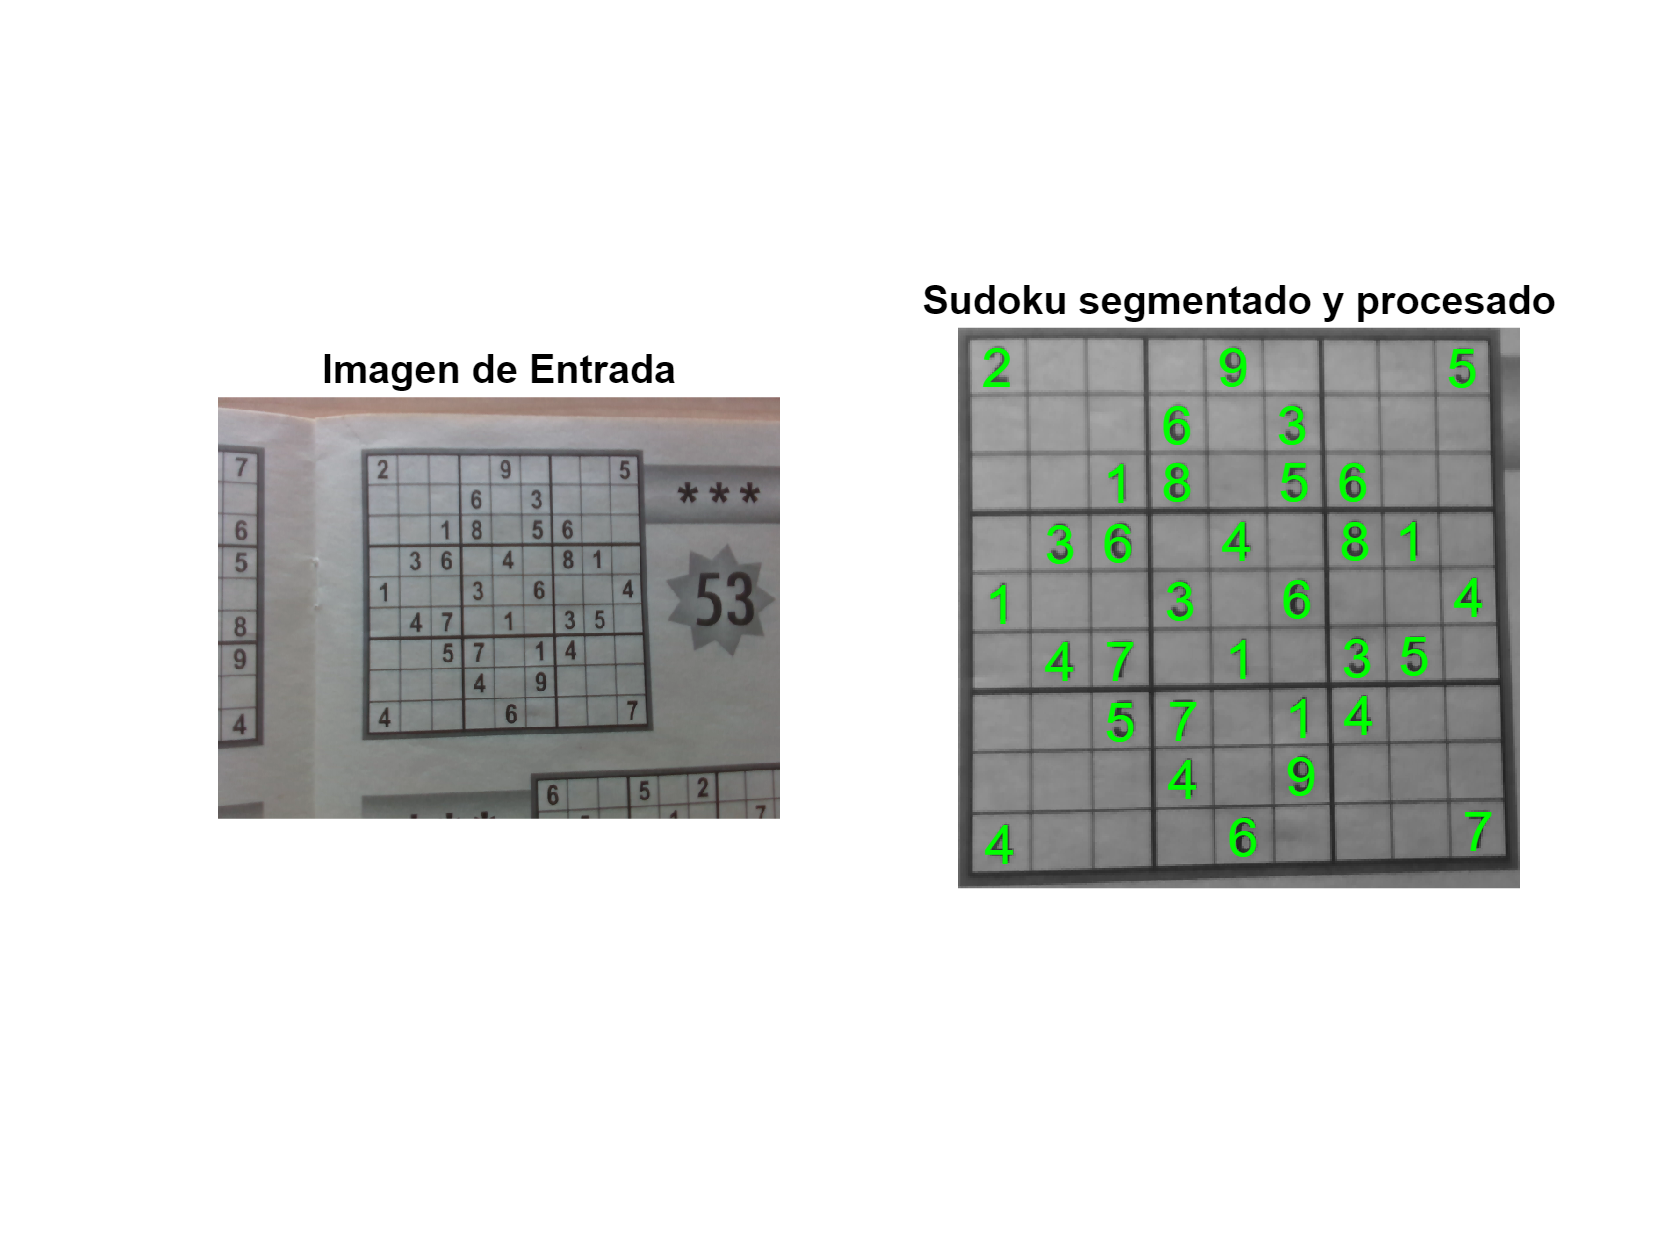

load netSudokus % Carga la red entrenada SudokuNet, si no se ha podido entrenar
load sudokus % Carga 8 imágenes con sudokus (sudo1 .. sudo8)
load histograma_celda % Carga el histograma que debe tener un digito
tam = [28,28]; % Tamaño de las imágenes
%-----------------------------------------------------------------------
im = sudo2; % Seleccionar una de las imágenes.
[im_sudoku,celdas] = BuscarCeldasSudoku(im,0);
figure
subplot(1,2,1),imshow(im); title ('Imagen de Entrada');
subplot(1,2,2),imshow(im_sudoku),hold on,
title ('Sudoku segmentado y procesado');
for k = 1:numel(celdas)
 if (celdas(k).ocu)
    num = PreprocesaNum(celdas(k).im,tam,h,1);
    c = classify(netSudokus,num);
    text(celdas(k).xcen,celdas(k).ycen,char(c),'FontSize',14,'Color',[0 1 0],'HorizontalAlignment', 'center');
 end
end

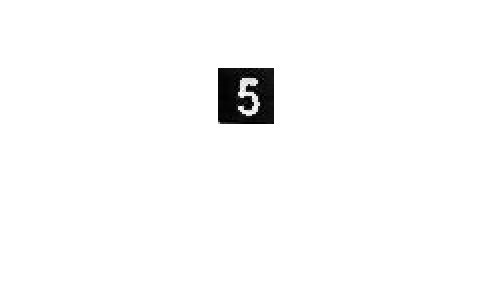

figure
imshow(readimage(imds,1750))

countEachLabel(imdsTrain)

ans = 9×2 table
    Label    Count
    _____    _____

      1       265 
      2       265 
      3       265 
      4       265 
      5       265 
      6       265 
      7       265 
      8       265 
      9       265 


length(layers)

ans = 11

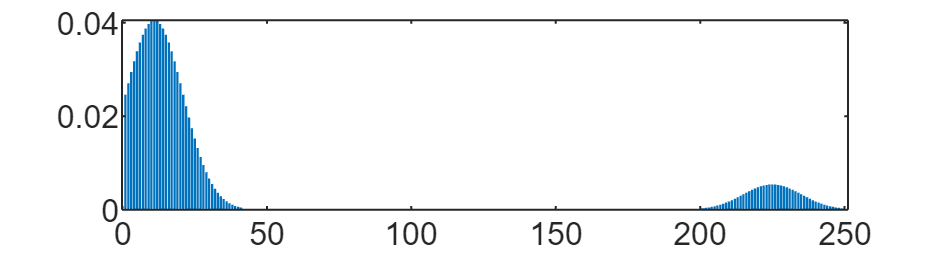

bar(h)